close all;
clear;
clc;
cluster = GetCluster(result, 5e-8, 4);
ScatterCluster(result, cluster);

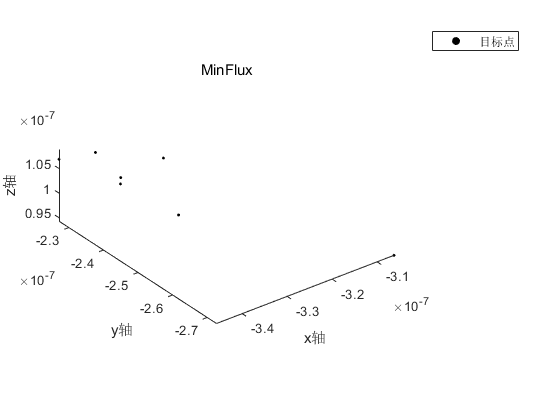

temp = cursor_info.Position;
data = result;
for i = 1 : size(cluster, 2)
    ClusterP = cluster{i};
    for j = ClusterP
        if isequal([data(j, 1), data(j, 2), data(j, 3)], temp)
            aim = [];
            for k = ClusterP
            f = scatter3(data(k, 1), data(k, 2), data(k, 3), 5, [0, 0, 0], 'filled');
            aim = [aim; [data(k, 1), data(k, 2), data(k, 3)]];
            hold on;
            end
            hold off;
        end
    end    
end

axis equal;
title('MinFlux');
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
legend(f, '目标点');
% set(gca, 'FontSize', 16, 'FontWeight', 'bold');
% grid on;
grid off;

M = aim;
[num, dim] = size(M);
L1 = ones(num,1);
A = inv(M'*M)*M'*L1;  % 求解平面法向量
B = zeros((num-1)*num/2,3);
 
count = 0;
for i = 1 : num-1
    for j = i+1 : num   
        count = count+1;
        B(count, :) = M(j, :) - M(i, :);
    end    
end
 
L2 = zeros((num-1)*num/2, 1);
count = 0;
for i = 1 : num-1
    for j = i+1 : num
        count = count+1;
        L2(count) = (M(j,1)^2+M(j,2)^2+M(j,3)^2-M(i,1)^2-M(i,2)^2-M(i,3)^2)/2;
    end
end
 
D = zeros(4, 4);
D(1:3, 1:3) = (B'*B);
D(4, 1:3) = A';
D(1:3, 4) = A;
 
L3 = [B'*L2; 1];
C = inv(D')*(L3);  % 求解空间圆圆心坐标
C = C(1:3);
 
radius = 0;
for i = 1:num
    tmp = M(i, :) - C';
    radius = radius + sqrt(tmp(1)^2+tmp(2)^2+tmp(3)^2);
end
r = radius/num;  % 空间圆拟合半径
 
f1 = plot3(M(:, 1), M(:, 2), M(:, 3), '.k');
hold on;

n = A;
c = C;
theta = (0 : 2*pi/100 : 2*pi)';  % theta角从0到2*pi
a=cross(n,[1, 0, 0]);  % n与i叉乘，求取a向量
if ~any(a)  % 如果a为零向量，将n与j叉乘
    a = cross(n, [0, 1, 0]);
end
b = cross(n, a);  % 求取b向量
a = a/norm(a);  % 单位化a向量
b = b/norm(b);  % 单位化b向量
 
c1 = c(1)*ones(size(theta,1), 1);
c2 = c(2)*ones(size(theta,1), 1);
c3 = c(3)*ones(size(theta,1), 1);
 
x = c1+r*a(1)*cos(theta)+r*b(1)*sin(theta);  % 圆上各点的x坐标
y = c2+r*a(2)*cos(theta)+r*b(2)*sin(theta);  % 圆上各点的y坐标
z = c3+r*a(3)*cos(theta)+r*b(3)*sin(theta);  % 圆上各点的z坐标
 
f2 = plot3(x, y, z, '-r');
axis equal;
title('圆的拟合结果');
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
legend([f1, f2], '目标点', '拟合圆');
hold off;

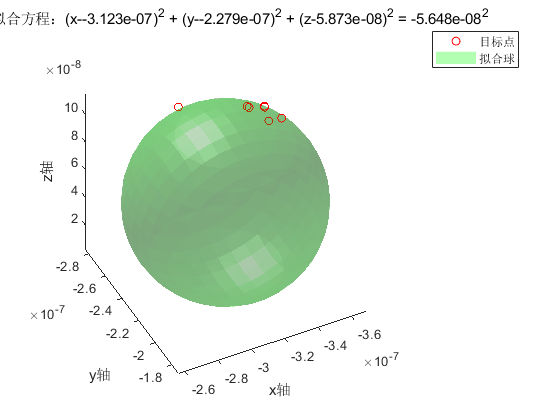

data = aim;
f = @(p, data) (data(:, 1) - p(1)).^2 + (data(:, 2) - p(2)).^2 + (data(:, 3) - p(3)).^2 - p(4)^2;
r = 5e-8;
bate = [0; 0; 0; r];
p = nlinfit(data, zeros(size(data, 1), 1), f, bate);

f1 = plot3(data(:, 1), data(:, 2), data(:, 3), 'or');
hold on;
m = max(abs(max(data, [], 'all')), abs(min(data, [], 'all'))) + r;
[X,Y,Z] = meshgrid(linspace(-m, m));
V = (X-p(1)).^2 + (Y-p(2)).^2 + (Z-p(3)).^2 - p(4)^2;
fv = isosurface(X, Y, Z, V, 0);

f2 = patch(fv, 'FaceColor', 'g', 'EdgeColor', 'None');
camlight('right') ;
axis equal;
alpha 0.3;
view([1, 1, 1]);
title(append('球的拟合方程：', sprintf('(x-%.3e)^2 + (y-%.3e)^2 + (z-%.3e)^2 = %.3e^2', p(1), p(2), p(3), p(4))));
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
legend([f1, f2], '目标点', '拟合球');
hold off;